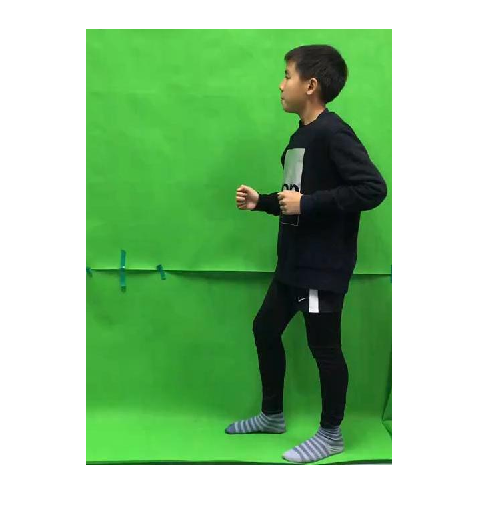

img = im2double(imread("crop\1crop\00001.jpg"));
imshow(img);

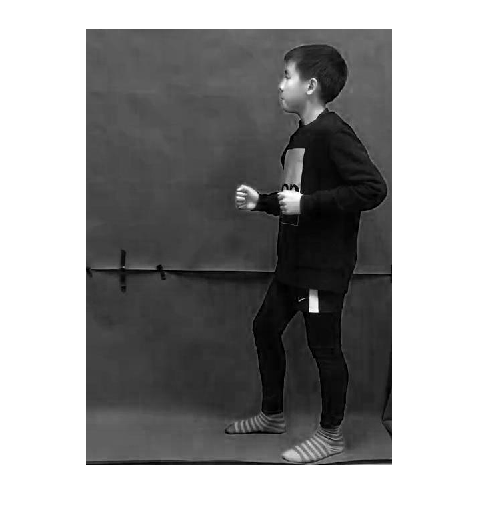

R = img(:, :, 1);
G = img(:, :, 2);
B = img(:, :, 3);
imshow(R);

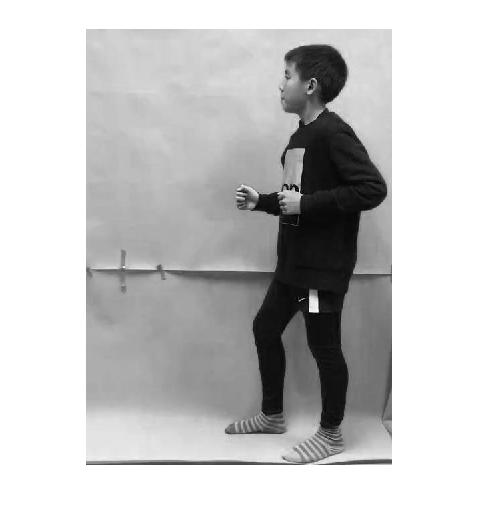

imshow(G);

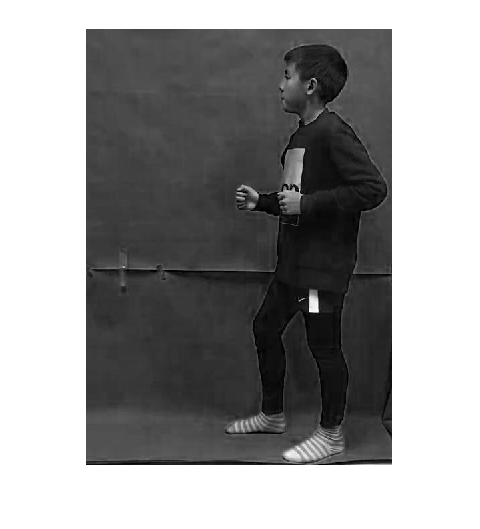

imshow(B);

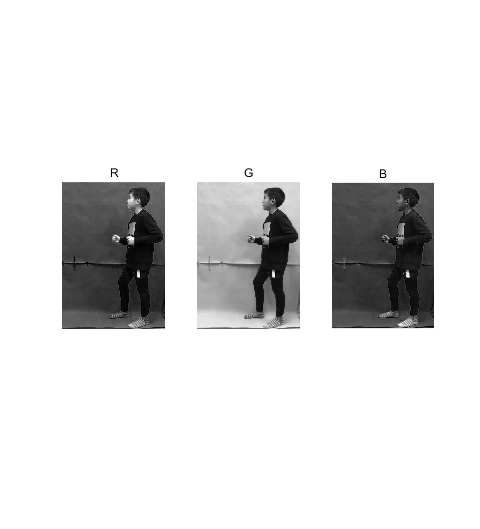

figure(1);
ax1(1)=subplot(1,3,1);imshow(R),title('R')
ax1(2)=subplot(1,3,2);imshow(G),title('G')
ax1(3)=subplot(1,3,3);imshow(B),title('B')
linkaxes(ax1);

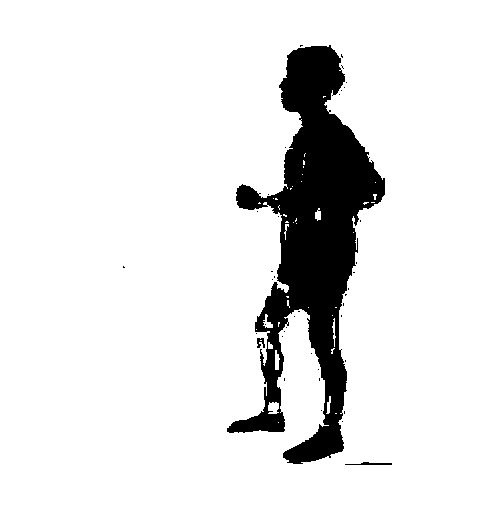

%mask = G > 0.4 & R + B < 0.8;
mask = (G ./ (R + G + B) > 0.45);
figure;imshow(mask);

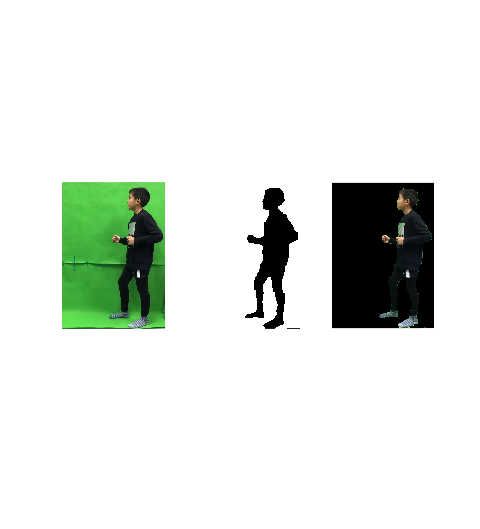

se=strel('disk',7);
mask=imopen(mask,se);
se=strel('disk',3);
mask=imclose(mask,se);
R(mask) = 0;
G(mask) = 0;
B(mask) = 0;
masked = img;
masked(:, :, 1) = R;
masked(:, :, 2) = G;
masked(:, :, 3) = B;
figure(2);
ax2(1)=subplot(1,3,1);imshow(img)
ax2(2)=subplot(1,3,2);imshow(mask)
ax2(3)=subplot(1,3,3);imshow(masked)
linkaxes(ax2);